#                                NEXT GEN HEALTH ANALYTIC

#                                              Monthly Report

             

% Import report API classes (optional)
import mlreportgen.report.*
import mlreportgen.dom.*
% Add report container (required)
rpt = Report('Demo','pdf');

% Add content to container (required)
% Types of content added here: title 
% page and table of contents reporters
titlepg = TitlePage;
titlepg.Title = 'Next Gen Health Analytics';
image = FormalImage('mathworks.jpeg');
titlepg.Author = 'Monthly Report';
add(rpt,titlepg);
add(rpt,image);
add(rpt,TableOfContents);
%figure = Figure();
% Add content to report sections (optional)
% Text and formal image added to chapter


chap1 = Chapter('Introduction');
p1=Paragraph('This is the demo for report generation.The data will be fetched monthly from thingspeak channel and will be analysed accordingly.')

p1 =   Paragraph with properties:

        OutlineLevel: []
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
              HAlign: []
     OuterLeftMargin: []
     FirstLineIndent: []
           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×1 mlreportgen.dom.Text]
                 Tag: 'dom.Paragraph:40039'
                  Id: '40039'


p2=Paragraph('Disclaimer:Not all graphs n charts are shown in this report.This report is just for example purpose.')

p2 =   Paragraph with properties:

        OutlineLevel: []
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
              HAlign: []
     OuterLeftMargin: []
     FirstLineIndent: []
           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×1 mlreportgen.dom.Text]
                 Tag: 'dom.Paragraph:40041'
                  Id: '40041'


add(rpt,chap1);
add(rpt,p1);
add(rpt,p2);


chap2 = Chapter('distribution of disease ');
data_temp = thingSpeakRead(717702,'Fields',[1,2,3,4],'NumMinutes',300,'OutputFormat','table') ;
data_temp.Disease = categorical (data_temp.Disease);
gender = categorical (data_temp.Gender);
m_val = unique (data_temp.Disease );
m=arrayfun(@(x) sum(data_temp.Disease==x),m_val);
pie(m);

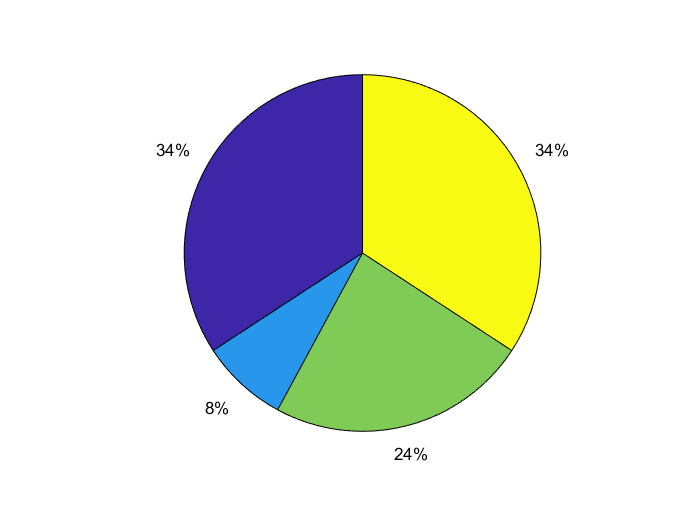

figure = Figure();
m= Image(getSnapshotImage(figure,rpt));

m.Width = '6in';
m.Height= [];
p3=Paragraph('This Pie chart gives information about percentage of each disease out of total registered cases.This will help to determine which disease is prevailing the most in the country.')

p3 =   Paragraph with properties:

        OutlineLevel: []
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
              HAlign: []
     OuterLeftMargin: []
     FirstLineIndent: []
           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×1 mlreportgen.dom.Text]
                 Tag: 'dom.Paragraph:40485'
                  Id: '40485'


add(rpt,chap2);
add(rpt,m)
add(rpt,p3)

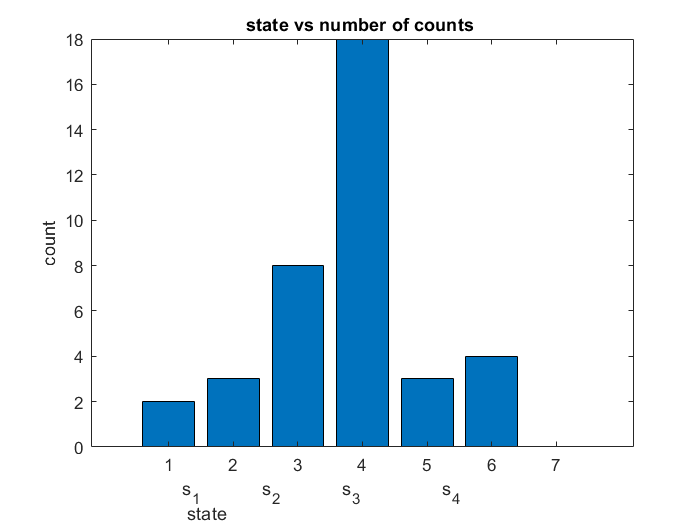

chap3 = Chapter('States vs Diseases count');
data_temp = thingSpeakRead(717702,'Fields',[1,2,3],'NumMinutes',300,'OutputFormat','table') ;
%y=height(data_temp);
data_temp.State = categorical (data_temp.State);
m_val = unique (data_temp.State);
n=arrayfun(@(x) sum(data_temp.State==x),m_val);
bar(n);
xlabel('s_1            s_2            s_3                s_4                \newline state ');
ylabel('count');
title ('state vs number of counts ');
figure = Figure();
n= Image(getSnapshotImage(figure,rpt));

n.Width = '6in';
n.Height= [];
p4=Paragraph('This graph will be generated for each disease individually.This gives authorities insight about the number of cases in particular state and how it is as compared to national count')

p4 =   Paragraph with properties:

        OutlineLevel: []
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
              HAlign: []
     OuterLeftMargin: []
     FirstLineIndent: []
           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×1 mlreportgen.dom.Text]
                 Tag: 'dom.Paragraph:40590'
                  Id: '40590'


add(rpt,chap3);
add(rpt,n);
add(rpt,p4);

chap4 = Chapter('Age wise classification');
readChannelID = 717702; 
AgeFieldID = 1;    
readAPIKey = 'QAESIJ22Z0SRF47C';   
a_d = thingSpeakRead(readChannelID,'Fields',AgeFieldID,...
    'NumMinutes',100*60, 'ReadKey',readAPIKey); %Time is sec change accordingly.

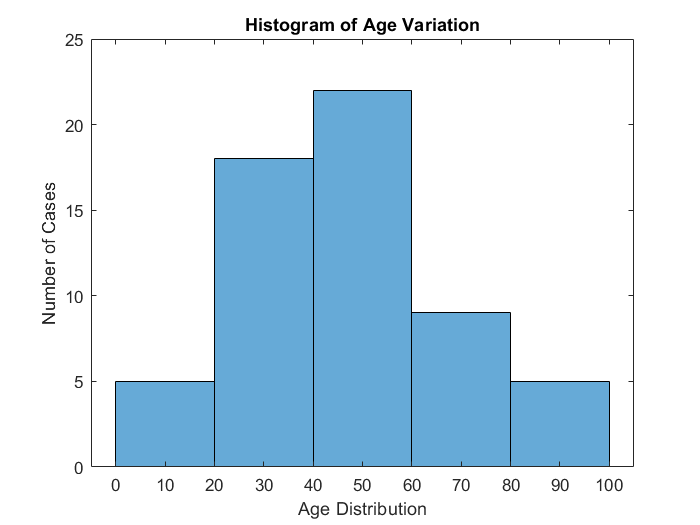

histogram(a_d); 
xlabel('Age Distribution'); 
ylabel('Number of Cases');
title('Histogram of Age Variation');
figure = Figure();
a_d= Image(getSnapshotImage(figure,rpt));

a_d.Width = '6in';
a_d.Height= [];
add(rpt,chap4);
add(rpt,a_d);

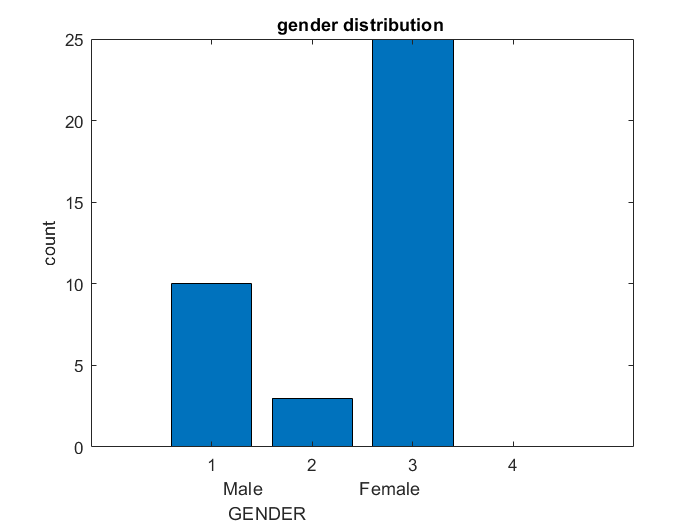


chap5 = Chapter('Classification according to gender');
% Enter your MATLAB code below
data_temp = thingSpeakRead(717702,'Fields',[1,2,3],'NumMinutes',300,'OutputFormat','table') ;
y=height(data_temp);
data_temp.Gender = categorical (data_temp.Gender);
m_val = unique (data_temp.Gender);
g=arrayfun(@(x) sum(data_temp.Gender==x),m_val);
bar(g);
xlabel('Male                   Female                \newline GENDER ');
ylabel('count');
title('gender distribution ');


g= Image(getSnapshotImage(figure,rpt));

g.Width = '6in';
g.Height= [];

add(rpt,chap5);
add(rpt,g);


% Close the report (required)
close(rpt);
% Display the report (optional)
rptview(rpt);
